# Быстрое преобразование Фурье в MATLAB ч.2

Данный скрипт использует только ядро **MATLAB**

### **Частотный анализ синтезированного сигнала**

Создадим сигнал Х из трёх синусоид разной амплитуды и начальной фазы. Добавим белый гауссовский шум. 

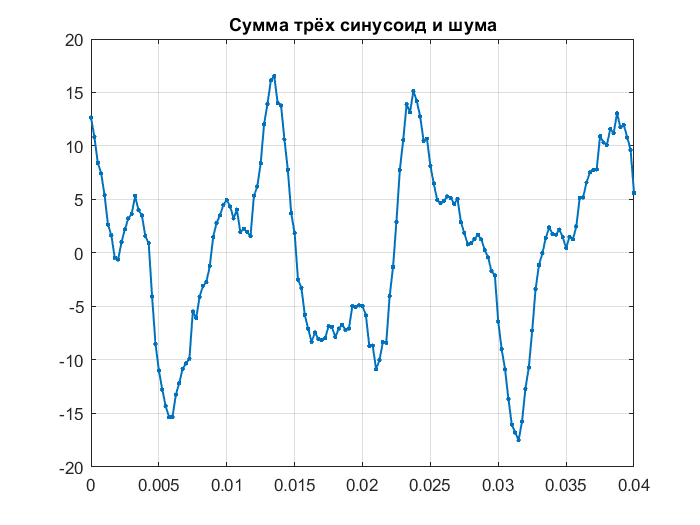

fs = 4000;
t = (0:1/fs:1 - 1/fs)';
n = length(t);

X = 10*cos(2*pi*80*t) +...
    5*cos(2*pi*200*t + pi/2) +...
    2.4*cos(2*pi*304*t - pi/6);

X = awgn(X,2);

plot(t,X,'LineWidth',1,'Marker','.')
xlim([0 0.04]); grid;
title('Сумма трёх синусоид и шума')

Оценим спектр исходного сигнала равномерным БПФ (функцией **fft**): 

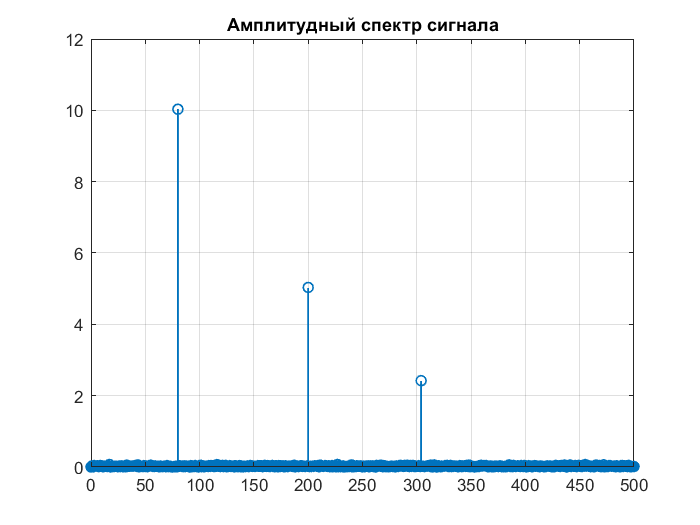

Y = fft(X)/n;

SpectrumX = 2*abs(Y);

ff = (0:n-1)*fs/n;

stem(ff,SpectrumX,'LineWidth',1)
xlim([0 500])
ylim([0 12])
grid
title('Амплитудный спектр сигнала')

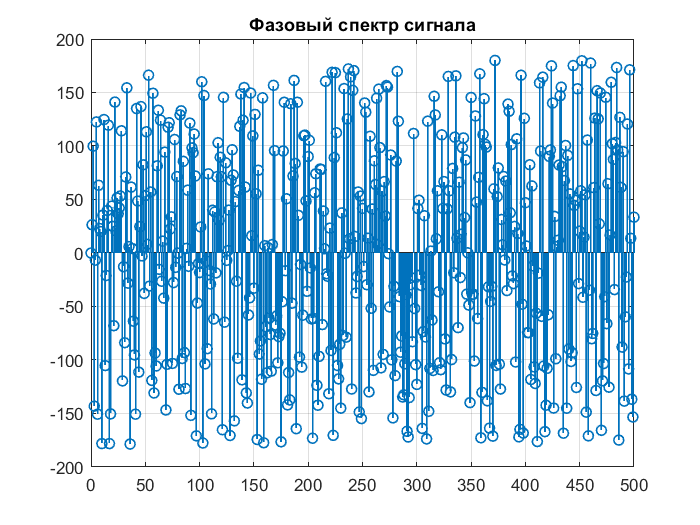


PhaseX = angle(Y) * 180/pi;
stem(ff,PhaseX,'LineWidth',1)
xlim([0 500])
ylim([-200 200])
grid
title('Фазовый спектр сигнала')

### **Частотный анализ измеренного сигнала**

Загрузим данные из mat-файла и визуализируем сигнал: 

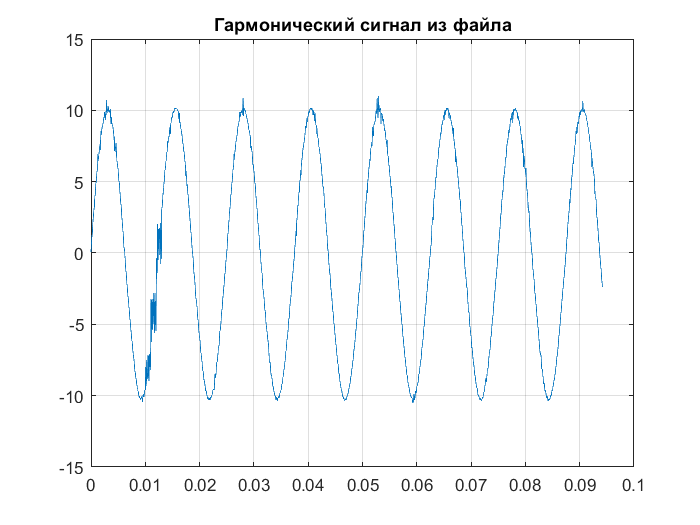

load 80hz;
plot(t80,sig80);
title('Гармонический сигнал из файла')
grid

Зададим параметры БПФ и визуализируем спектр сигнала:

nsamp = length(t80);
fs = 1/mean(diff(t80));

RBW = 20   % частотный шаг разложения фурье

RBW = 20

nfft = round(fs/RBW)   % параметр функции FFT

nfft = 2174

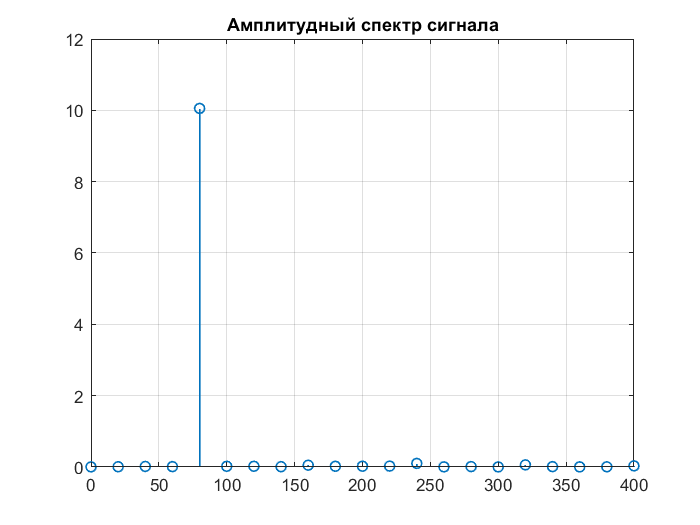


Y = fft(sig80,nfft)/nfft;  
SpectrumX = 2*abs(Y);   % получение спектра из массива, дополненного нулями
ff=(0:nfft-1)*fs/nfft; 
  
stem(ff,SpectrumX,'LineWidth',1);
xlim([0 400]);
grid;
title('Амплитудный спектр сигнала')